# Systematic review of SysID - Expectation-Maximization algorithm

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Jingxiao Liu
% Inferlab, CEE, CMU
% June, 2019
% Matlab live script for introducing expectation-maximization algorithm
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

5.1 State space model


$$\begin{array}{l}
x\left\lbrack k+1\right\rbrack =A\;x\left\lbrack k\right\rbrack +B\;u\left\lbrack k\right\rbrack +\epsilon \left\lbrack k\right\rbrack \\
y\left\lbrack k+1\right\rbrack =C\;x\left\lbrack k+1\right\rbrack +\eta \left\lbrack k+1\right\rbrack \\
\epsilon \left\lbrack k\right\rbrack \sim N\left(0,Q\right)\\
\eta \left\lbrack k\right\rbrack \sim N\left(0,R\right)
\end{array}$$


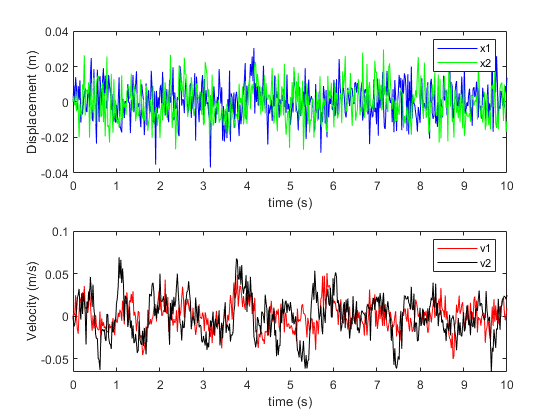

clc;
clear;
close all;
addpath ../functions/
T = 10; %length of time duration
nt = 500; %number of time stamps
Fs = nt/T;
F = csvread(['../data/ambient.csv']); %load data
X = csvread(['../data/2dof_noP.csv']); %load data
tspan=linspace(0,T,nt);
figure(1)
plot_dv(tspan,X')

m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2

% system matrices
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix
dt = tspan(2)-tspan(1); % delta time
C = [1,0,0,0;0,0,1,0];
Ac = [0,0,1,0;
     0,0,0,1;
     -K(1,1)/M(1,1),-K(1,2)/M(1,1),-Damp(1,1)/M(1,1),-Damp(1,2)/M(1,1);
     -K(2,1)/M(2,2),-K(2,2)/M(2,2),-Damp(2,1)/M(2,2),-Damp(2,2)/M(2,2)];
A = Ac*dt;
A = expm(A);
Bc = [0,0,0,0;
    0,0,0,0;
    0,0,1/M(1,1),0;
    0,0,0,1/M(2,2)];
B = inv(Ac)*(A-eye(4))*Bc;    

Partial observation

Y = C*X;

5.2 Kalman filter


$$\begin{array}{l}
\hat{x} \left\lbrack k+1\left|k\right.\right\rbrack =A\;\hat{x} \left\lbrack k\left|k\right.\right\rbrack +B\;u\left\lbrack k\right\rbrack \\
\Sigma \left\lbrack k+1\left|k\right.\right\rbrack =A\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T +Q\\
K\left\lbrack k+1\right\rbrack =\Sigma \left\lbrack k+1\left|k\right.\right\rbrack C^T {\left(C\Sigma \left\lbrack k+1\left|k\right.\right\rbrack C^T +R\right)}^{-1} \\
\hat{x} \left\lbrack k+1\left|k+1\right.\right\rbrack =\hat{x} \left\lbrack k+1\left|k\right.\right\rbrack +K\left\lbrack k+1\right\rbrack \left(y\left\lbrack k+1\right\rbrack -C\hat{x} \left\lbrack k+1\left|k\right.\right\rbrack \right)\\
\Sigma \left\lbrack k+1\left|k+1\right.\right\rbrack =\Sigma \left\lbrack k+1\left|k\right.\right\rbrack -K\left\lbrack k+1\right\rbrack C\Sigma \left\lbrack k+1\left|k\right.\right\rbrack 
\end{array}$$


5.2.1 Deriving the posteriori estimate covariance matrix


$$\begin{array}{l}
\Sigma \left\lbrack k\left|k\right.\right\rbrack =\mathrm{cov}\left(x\left\lbrack k\right\rbrack -\hat{x} \left\lbrack k|k\right\rbrack \right)=\mathrm{cov}\left\lbrack x\left\lbrack k\right\rbrack -\left(\hat{x} \left\lbrack k|k-1\right\rbrack +K\left\lbrack k\right\rbrack \left(y\left\lbrack k+1\right\rbrack -C\hat{x} \left\lbrack k+1\left|k\right.\right\rbrack \right)\right)\right\rbrack \\
=\mathrm{cov}\left\lbrack x\left\lbrack k\right\rbrack -\left(\hat{x} \left\lbrack k|k-1\right\rbrack +K\left\lbrack k\right\rbrack \left(C\;x\left\lbrack k\right\rbrack +\eta \left\lbrack k\right\rbrack -C\hat{x} \left\lbrack k+1\left|k\right.\right\rbrack \right)\right)\right\rbrack \\
=\mathrm{cov}\left\lbrack \left(I-K\left\lbrack k\right\rbrack C\right)\left(x\left\lbrack k\right\rbrack -\hat{x} \left\lbrack k|k-1\right\rbrack \right)-K\left\lbrack k\right\rbrack \eta \left\lbrack k\right\rbrack \right\rbrack \\
=\left(I-K\left\lbrack k\right\rbrack C\right)\Sigma \left\lbrack k\left|k-1\right.\right\rbrack {\left(I-K\left\lbrack k\right\rbrack C\right)}^T +K\left\lbrack k\right\rbrack R\;K{\left\lbrack k\right\rbrack }^T 
\end{array}$$


5.2.2 Deriving Kalman gain

We seek to minimize the mean-square error estimator $E\left\lbrack {\left\|x\left\lbrack k\right\rbrack -\hat{x} \left\lbrack k|k\right\rbrack \right\|}^2 \right\rbrack$, which is quivalent to minimize


$$\begin{array}{l}
\Sigma \left\lbrack k\left|k\right.\right\rbrack =\left(I-K\left\lbrack k\right\rbrack C\right)\Sigma \left\lbrack k\left|k-1\right.\right\rbrack {\left(I-K\left\lbrack k\right\rbrack C\right)}^T +K\left\lbrack k\right\rbrack R\;K{\left\lbrack k\right\rbrack }^T \\
\frac{\partial }{\partial K\left\lbrack k\right\rbrack }\mathrm{tr}\left(\Sigma \left\lbrack k\left|k\right.\right\rbrack \right)=-2{\left(C\;\Sigma \left\lbrack k\left|k-1\right.\right\rbrack \right)}^T +2K\left\lbrack k\right\rbrack \left(C\Sigma \left\lbrack k+1\left|k\right.\right\rbrack C^T +R\right)
\end{array}$$


Then,


$$K\left\lbrack k+1\right\rbrack =\Sigma \left\lbrack k+1\left|k\right.\right\rbrack C^T {\left(C\Sigma \left\lbrack k+1\left|k\right.\right\rbrack C^T +R\right)}^{-1}$$


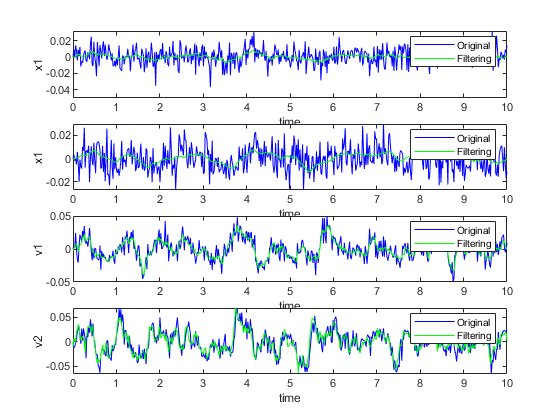

Q = diag([1e-6,1e-6,1e-6,1e-6]); % initialize process noise covariance
R = diag([1e-4,1e-4]); % initialize observation noise covariance
xkk = X(:,1);
pkk = B*Q*B';
Xk1k = zeros(4, size(Y,2));
Xkk = zeros(4, size(Y,2));
Pkk = zeros(4, 4, size(Y,2));
Pk1k = zeros(4, 4, size(Y,2));
for i = 1:size(Y,2)
    xk1k = A * xkk + B*[0;0;F(1,i);F(2,i)];
    pk1k = A * pkk * A' + Q;
    K = pk1k*C'*inv(R + C*pk1k*C');
    xkk = xk1k + K * (Y(:,i)-C*xk1k);
    pkk = pk1k - K*C*pk1k;
    Xk1k(:,i) = xk1k;
    Xkk(:,i) = xkk;
    Pk1k(:,:,i) = pk1k;
    Pkk(:,:,i) = pkk;
end
ylabels = {'x1','x1','v1','v2'};
figure(1)
plot_com(tspan,X,Xkk,ylabels,'Original','Filtering')

5.3 Kalman smoothing

5.3.1 Forward pass: Kalman filter computes $\left(x\left\lbrack k\right\rbrack |y\left\lbrack 0:k\right\rbrack \right)$, which is real-time,

5.3.2 Backward pass: computing $\left(x\left\lbrack k\right\rbrack |y\left\lbrack 0:T\right\rbrack \right)$, which is post-processing.


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
x\left\lbrack k|k\right\rbrack \\
x\left\lbrack k+1|k\right\rbrack 
\end{array}\right\rbrack =N\left(\left\lbrack \begin{array}{c}
E\left\lbrack x\left\lbrack k|k\right\rbrack \right\rbrack \\
E\left\lbrack x\left\lbrack k+1|k\right\rbrack \right\rbrack 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\mathrm{var}\left(x\left\lbrack k|k\right\rbrack \right) & \mathrm{cov}\left(x\left\lbrack k|k\right\rbrack ,x\left\lbrack k+1|k\right\rbrack \right)\\
\mathrm{cov}\left\lbrack x\left\lbrack k+1|k\right\rbrack ,x\left\lbrack k|k\right\rbrack \right\rbrack  & \mathrm{var}\left(x\left\lbrack k+1|k\right\rbrack \right)
\end{array}\right\rbrack \right)\\
=N\left(\left\lbrack \begin{array}{c}
\hat{x} \left\lbrack k|k\right\rbrack \\
\hat{x} \left\lbrack k+1|k\right\rbrack 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\Sigma \left\lbrack k\left|k\right.\right\rbrack  & \Sigma \left\lbrack k+1\left|k\right.\right\rbrack A^T \\
A\Sigma \left\lbrack k+1\left|k\right.\right\rbrack  & \Sigma \left\lbrack k+1\left|k\right.\right\rbrack 
\end{array}\right\rbrack \right)\\
\mathrm{cov}\left(x\left\lbrack k+1|k\right\rbrack ,x\left\lbrack k|k\right\rbrack \right)=A\;\mathrm{cov}\left(x\left\lbrack k|k\right\rbrack ,x\left\lbrack k|k\right\rbrack \right)+\mathrm{cov}\left(B\;u\left\lbrack k+1\right\rbrack ,x\left\lbrack k|k\right\rbrack \right)=A\Sigma \left\lbrack k+1\left|k\right.\right\rbrack 
\end{array}$$


Then,


$$\begin{array}{l}
\left(x\left\lbrack k|k\right\rbrack |x\left\lbrack k+1|k\right\rbrack =\tilde{x} \left\lbrack k+1\right\rbrack \right)\\
=N\left(\hat{x} \left\lbrack k|k\right\rbrack +\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^T \left(\tilde{x} \left\lbrack k+1\right\rbrack -\hat{x} \left\lbrack k+1|k\right\rbrack \right),\Sigma \left\lbrack k\left|k\right.\right\rbrack -\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^{-1} A\Sigma \left\lbrack k\left|k\right.\right\rbrack \right)
\end{array}$$


We do not know $\tilde{x} \left\lbrack k+1\right\rbrack$, but $\tilde{x} \left\lbrack k+1\right\rbrack \sim x\left\lbrack k+1|0:T\right\rbrack$, thus,

(Law of total expectation)


$$\begin{array}{l}
\hat{x} \left\lbrack k|0:T\right\rbrack =E\left\lbrack x\left\lbrack k|0:T\right\rbrack \right\rbrack =E_{x\left\lbrack k+1|0:T\right\rbrack } \left\lbrack E\left(x\left\lbrack k|k\right\rbrack |x\left\lbrack k+1|k\right\rbrack =x\left\lbrack k+1|0:T\right\rbrack \right)\right\rbrack \\
=\hat{x} \left\lbrack k|k\right\rbrack +\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^T \left(\hat{x} \left\lbrack k+1|0:T\right\rbrack -\hat{x} \left\lbrack k+1|k\right\rbrack \right)
\end{array}$$


(law of total variance)


$$\begin{array}{l}
\Sigma \left\lbrack k\left|0:T\right.\right\rbrack =\mathrm{Var}\left\lbrack x\left\lbrack k|0:T\right\rbrack \right\rbrack \\
=E_{x\left\lbrack k+1|0:T\right\rbrack } \left\lbrack \mathrm{Var}\left(x\left\lbrack k|k\right\rbrack |x\left\lbrack k+1|k\right\rbrack =x\left\lbrack k+1|0:T\right\rbrack \right)\right\rbrack +{\mathrm{Var}}_{x\left\lbrack k+1|0:T\right\rbrack } \left\lbrack E\left(x\left\lbrack k|k\right\rbrack |x\left\lbrack k+1|k\right\rbrack =x\left\lbrack k+1|0:T\right\rbrack \right)\right\rbrack \\
=\Sigma \left\lbrack k\left|k\right.\right\rbrack -\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^{-1} A\Sigma \left\lbrack k\left|k\right.\right\rbrack +\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^T \Sigma \left\lbrack k+1\left|0:T\right.\right\rbrack {\left(\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^{-1} \right)}^T 
\end{array}$$


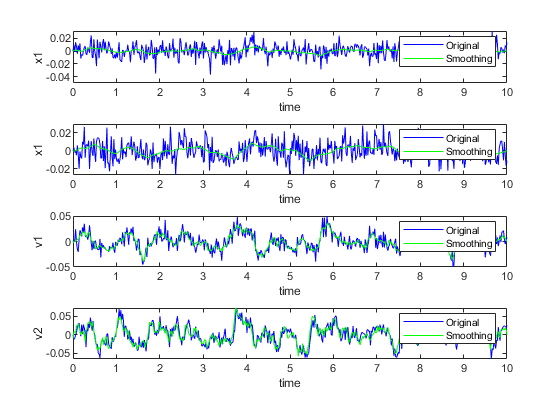

XT = zeros(4, size(Y,2));
PT = zeros(4, 4, size(Y,2));
for k=(size(Xk1k,2)-1):-1:1
    L(:,:,k) = Pkk(:,:,k) * A' * inv(Pk1k(:,:,k+1)+diag(ones(1,4)*1e-7));
    XT(:,k) = Xkk(:,k) + L(:,:,k) * ...
        (XT(:,k+1) - Xk1k(:,k+1));
    PT(:,:,k) = Pkk(:,:,k) + L(:,:,k) * ...
        (PT(:,:,k+1) - Pk1k(:,:,k+1)) * L(:,:,k)';
end
figure(3)
plot_com(tspan,X,XT,ylabels,'Original','Smoothing')

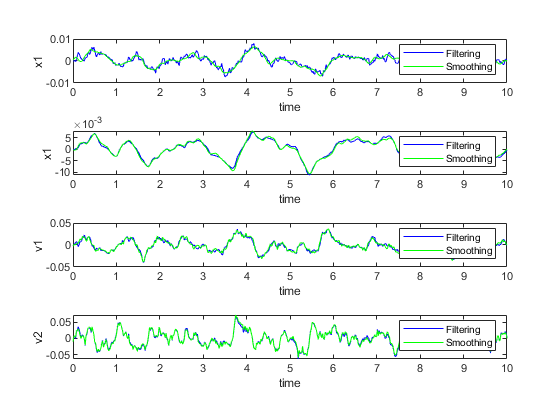

figure(4)
plot_com(tspan,Xkk,XT,ylabels,'Filtering','Smoothing')

 5.4 Log-likelihood function


$$\begin{array}{l}
L\left(A,B,C,u\left\lbrack 0:T\right\rbrack ,Q,R|x\left\lbrack 0:T\right\rbrack ,y\left\lbrack 0:T\right\rbrack \right)=\mathrm{log}\;p\left(x\left\lbrack 0:T\right\rbrack ,y\left\lbrack 0:T\right\rbrack |A,B,C,u\left\lbrack 0:T\right\rbrack ,Q,R\right)\\
=\mathrm{log}\;\prod_{k=0}^T p\left(x\left\lbrack k\right\rbrack |x\left\lbrack k-1\right\rbrack \right)p\left(y\left\lbrack k\right\rbrack |x\left\lbrack k\right\rbrack \right)\\
=\sum_{k=0}^{T-1} \mathrm{log}\;p\left(x\left\lbrack k+1\right\rbrack |x\left\lbrack k\right\rbrack \right)+\;\sum_{k=0}^T \mathrm{log}\;p\left(y\left\lbrack k\right\rbrack |x\left\lbrack k\right\rbrack \right)\\
=\frac{T}{2}\mathrm{log}|Q^{-1} |-\frac{1}{2}\sum_{k=0}^{T-1} \mathrm{tr}\left\lbrack {\left(x\left\lbrack k+1\right\rbrack -\mathrm{Ax}\left\lbrack k\right\rbrack -\mathrm{Bu}\left\lbrack k\right\rbrack \right)}^T Q^{-1} \left(x\left\lbrack k+1\right\rbrack -\mathrm{Ax}\left\lbrack k\right\rbrack -\mathrm{Bu}\left\lbrack k\right\rbrack \right)\right\rbrack \\
\;\;\;\;+\frac{T+1}{2}\mathrm{log}|R^{-1} |-\frac{1}{2}\sum_{k=0}^T \mathrm{tr}\left\lbrack {\left(y\left\lbrack k\right\rbrack -\mathrm{Cx}\left\lbrack k\right\rbrack \right)}^T R^{-1} \left(y\left\lbrack k\right\rbrack -\mathrm{Cx}\left\lbrack k\right\rbrack \right)\right\rbrack +\mathrm{const}
\end{array}$$


5.5 Maximize the expected log-likelihood function


$$\begin{array}{l}
\frac{\partial }{\partial A}E\left\lbrack L\left(A,B,C,u\left\lbrack 0:T\right\rbrack ,Q,R\left|x\left\lbrack 0:T\right\rbrack ,y\left\lbrack 0:T\right\rbrack \right.\right)\right\rbrack \equiv 0\\
A=\left(\sum_{k=0}^{T-1} \left\lbrack E\left\lbrack x\left\lbrack k\right\rbrack x{\left\lbrack k+1\right\rbrack }^T \left|y\left\lbrack 0:T\right\rbrack \right\rbrack -E\left\lbrack B\;u\left\lbrack k\right\rbrack x{\left\lbrack k\right\rbrack }^T \left|y\left\lbrack 0:T\right\rbrack \right.\right\rbrack \right\rbrack \right.\right){\left(\sum_{k=0}^{T-1} E\left\lbrack x\left\lbrack k\right\rbrack x{\left\lbrack k\right\rbrack }^T \left|y\left\lbrack 0:T\right\rbrack \right.\right\rbrack \right)}^{-1} \\
\frac{\partial }{\partial C}E\left\lbrack L\left(A,B,C,u\left\lbrack 0:T\right\rbrack ,Q,R\left|x\left\lbrack 0:T\right\rbrack ,y\left\lbrack 0:T\right\rbrack \right.\right)\right\rbrack \equiv 0\\
C=\left(\sum_{k=0}^T \left\lbrack E\left\lbrack y\left\lbrack k\right\rbrack x{\left\lbrack k\right\rbrack }^T \left|y\left\lbrack 0:T\right\rbrack \right.\right\rbrack \right.\right){\left(\sum_{k=0}^T E\left\lbrack x\left\lbrack k\right\rbrack x{\left\lbrack k\right\rbrack }^T \left|y\left\lbrack 0:T\right\rbrack \right.\right\rbrack \right)}^{-1} \\
\frac{\partial }{\partial Q^{-1} }E\left\lbrack L\left(A,B,C,u\left\lbrack 0:T\right\rbrack ,Q,R\left|x\left\lbrack 0:T\right\rbrack ,y\left\lbrack 0:T\right\rbrack \right.\right)\right\rbrack \equiv 0\\
Q=\frac{1}{T}\left\lbrace \sum_{k=0}^{T-1} E\left\lbrack {\left(x\left\lbrack k+1\right\rbrack -\textrm{Ax}\left\lbrack k\right\rbrack -\textrm{Bu}\left\lbrack k\right\rbrack \right)}^T \left(x\left\lbrack k+1\right\rbrack -\textrm{Ax}\left\lbrack k\right\rbrack -\textrm{Bu}\left\lbrack k\right\rbrack \right)\left|y\left\lbrack 0:T\right\rbrack \right.\right\rbrack \right\rbrace \\
\frac{\partial }{\partial R^{-1} }E\left\lbrack L\left(A,B,C,u\left\lbrack 0:T\right\rbrack ,Q,R\left|x\left\lbrack 0:T\right\rbrack ,y\left\lbrack 0:T\right\rbrack \right.\right)\right\rbrack \equiv 0\\
R=\frac{1}{T+1}\left\lbrace \sum_{k=0}^T E\left\lbrack {\left(y\left\lbrack k\right\rbrack -\textrm{Cx}\left\lbrack k\right\rbrack \right)}^T \left(y\left\lbrack k\right\rbrack -\textrm{Cx}\left\lbrack k\right\rbrack \right)\left|y\left\lbrack 0:T\right\rbrack \right.\right\rbrack \right\rbrace 
\end{array}$$


where


$$\begin{array}{l}
E\left(x\left\lbrack k\right\rbrack |y\left\lbrack 0:T\right\rbrack \right)=\hat{x} \left\lbrack k|0:T\right\rbrack \\
E\left(x\left\lbrack k\right\rbrack x{\left\lbrack k\right\rbrack }^T |y\left\lbrack 0:T\right\rbrack \right)=\Sigma \left\lbrack k\left|0:T\right.\right\rbrack +\hat{x} \left\lbrack k|0:T\right\rbrack \hat{x} {\left\lbrack k|0:T\right\rbrack }^T \\
E\left(x\left\lbrack k\right\rbrack x{\left\lbrack k+1\right\rbrack }^T |y\left\lbrack 0:T\right\rbrack \right)=\hat{x} \left\lbrack k|0:T\right\rbrack \hat{x} {\left\lbrack k+1|0:T\right\rbrack }^T \\
+\Sigma \left\lbrack k\left|k\right.\right\rbrack A^T \Sigma {\left\lbrack k+1\left|k\right.\right\rbrack }^T \left(\Sigma \left\lbrack k+1\left|0:T\right.\right\rbrack +\left(\hat{x} \left\lbrack k+1|0:T\right\rbrack -\hat{x} \left\lbrack k+1|k\right\rbrack \right)\hat{x} {\left\lbrack k+1|0:T\right\rbrack }^T \right)
\end{array}$$


[A,C,Q,R,llhs] = ss_em(A,C,Q,R,Y,X(:,1),Q);
figure(5)
plot(llhs)
xlabel('Iteration')
ylabel('Log-likelihood')
% [XT, PT, Exx, Ex1x, llh] = kalman_smoother(A,C,Q,R,Y,X(:,1),Q);
% figure(5)
% plot_com(tspan,X,XT,ylabels,'Original','Smoothing')